% Tim Booher, Lockheed Martin...
% Requests coregistration of targets (one used, one used)
clear; close all; clc;

## original images

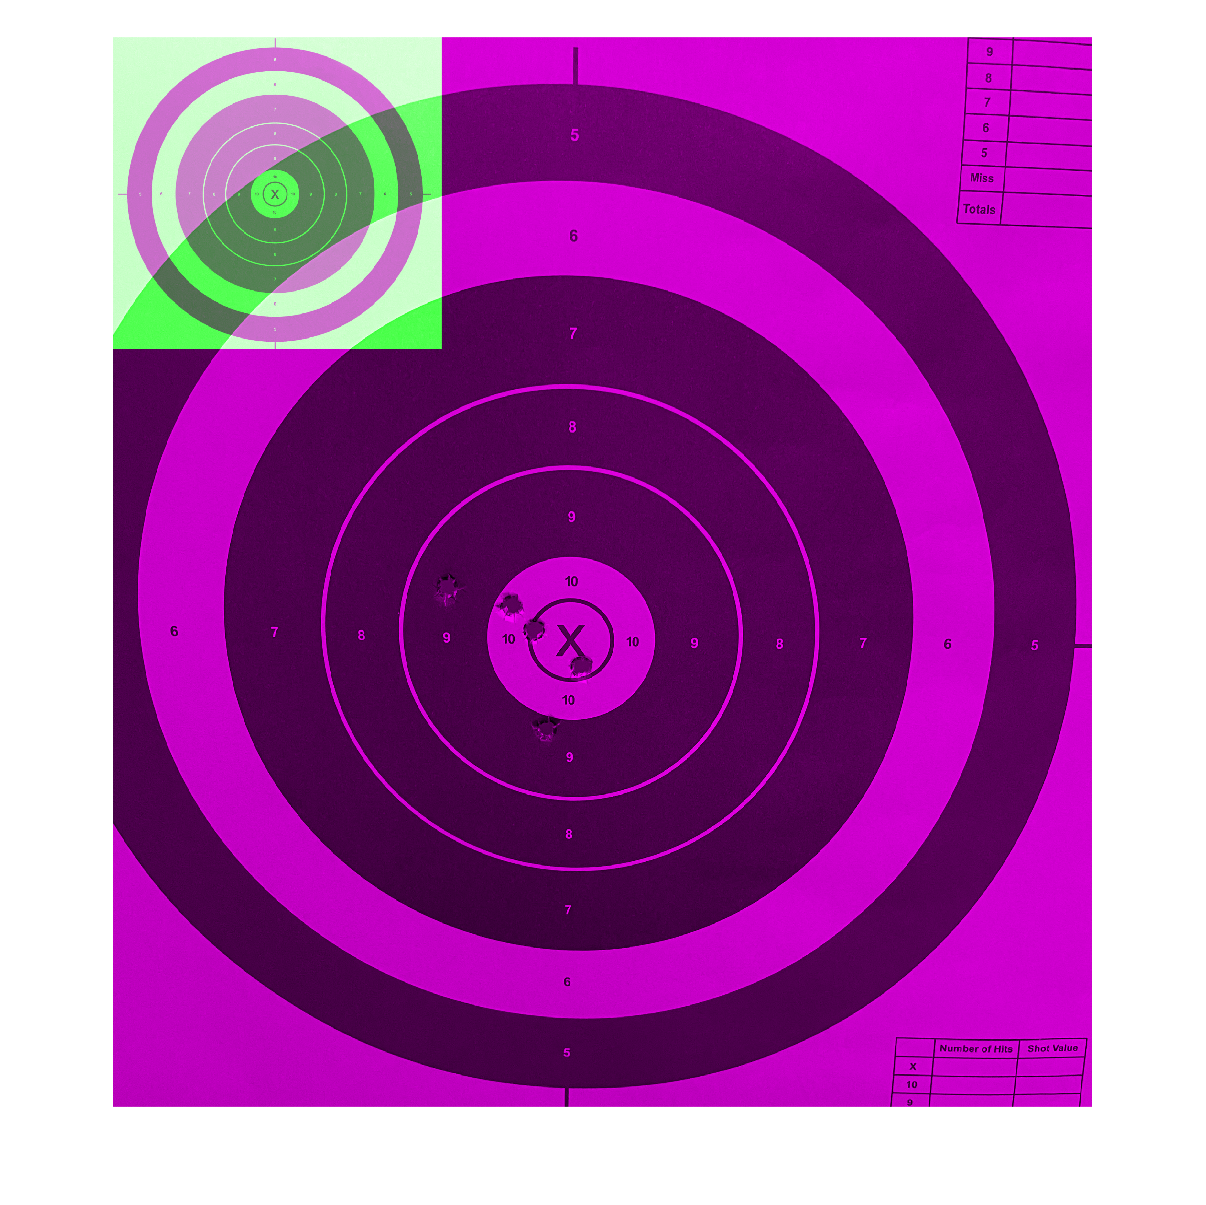

% here we try to see how much of a challenge we are facing
cleanTarget = imread("files/flat.png");
used = imread("files/2021-09-12 14.38.26.jpg");
originalFig = figure('Name', 'Originals');
imshowpair(cleanTarget, used)

## Doc Example:

For the GENERAL CASE of pointwise feature registration, see the doc for fitgeotrans; with corresponding points, we can generate a tform, with which we can "undistort" one image (used) to align with the other (target).

For THIS problem, all we need to do is calculate and align the centers, and rescale one image to the size of the other! Color thresholding and imfindcircle are quite useful here. For the former, you can use colorThresholder(), but in this case it's pretty easy:


% First the clean target
[~, ~, bTarget] = imsplit(cleanTarget);
redTarget = bTarget < 100;
redTarget = bwareafilt(redTarget, 1);

% CircleFinder(redTarget)
% We can specify the radius range manually, or we can do it automatically:


## define circles function


% detectCircles(redTarget, round([diamCleanTarget/2 * 0.8, diamCleanTarget/2 * 1.2]))

## time to show stuff

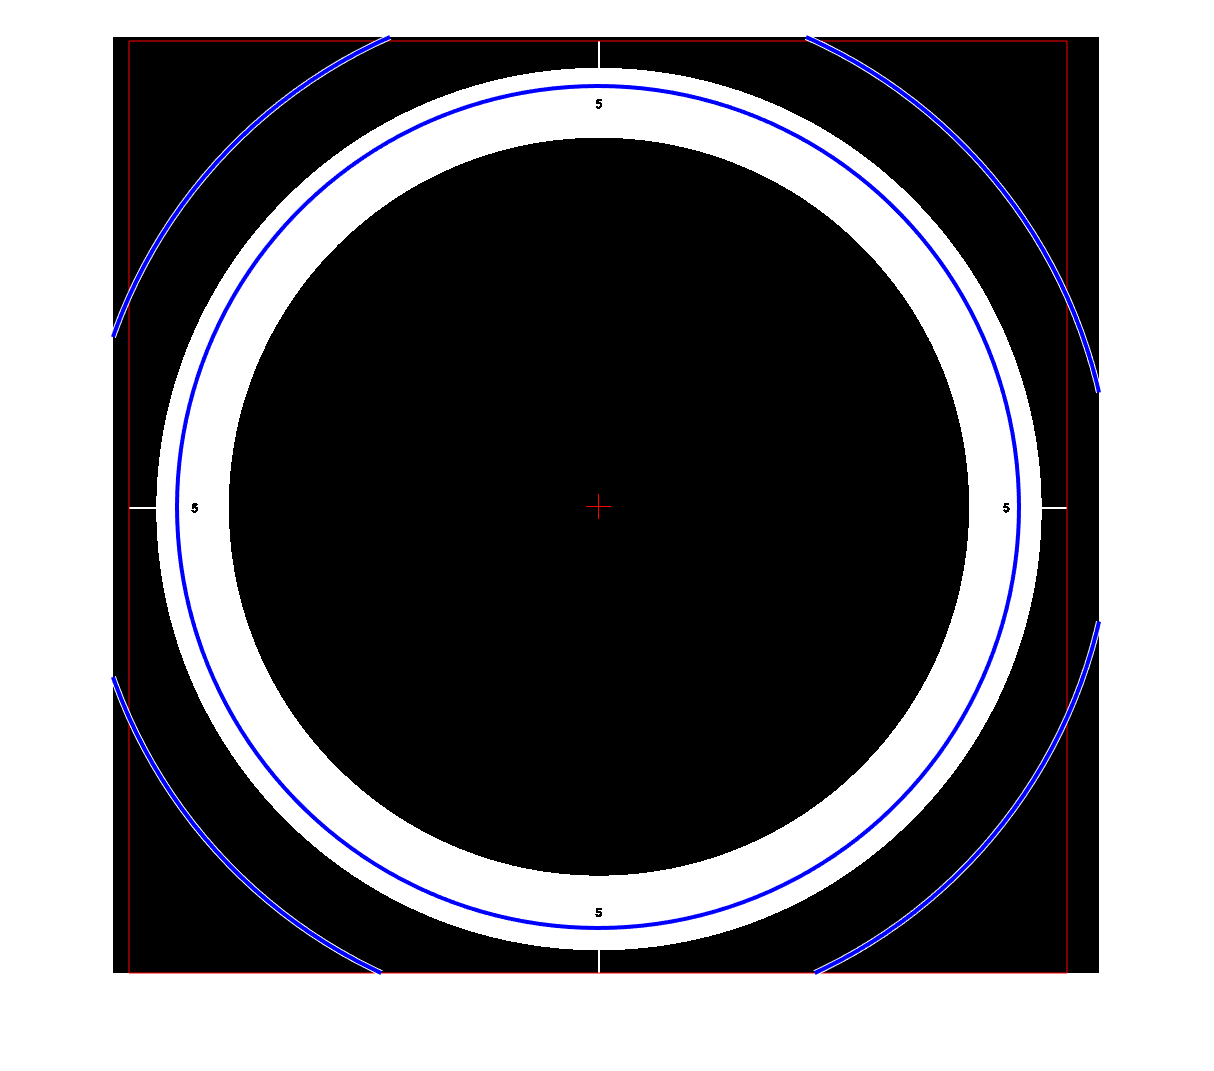

% delete this

## Now we need to find the center

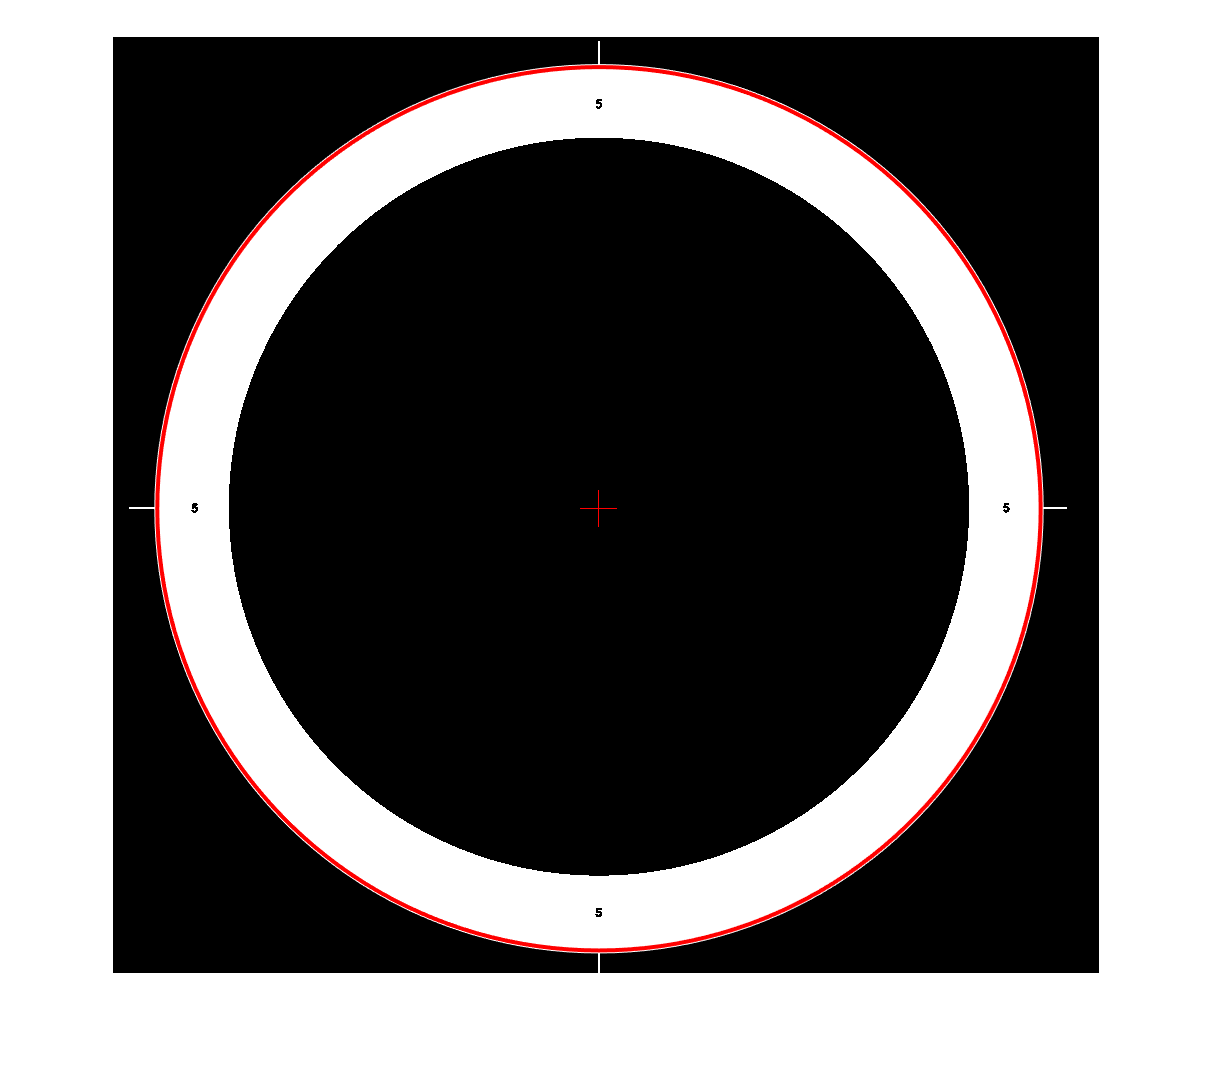

clf;
imshow(redTarget);
[cleanTargetCenter, cleanTargetRadius] = detectCircles(redTarget, radiusRangeCleanTarget);
cleanTargetCenter = cleanTargetCenter(1, :);
cleanTargetRadius = cleanTargetRadius(1);
viscircles(cleanTargetCenter, cleanTargetRadius);
hold on
plot(cleanTargetCenter(1), cleanTargetCenter(2), 'r+', 'MarkerSize', 18);

## Now the used target


[~, ~, bUsed] = imsplit(used);
redUsed = bUsed < 100;
redUsed = bwareafilt(redUsed, 1);
stats = regionprops(redUsed, 'BoundingBox');
BB = stats.BoundingBox;
diamUsedTarget = mean(BB(3:4));

## try 2 on Used target circle detection


radiusRangeUsedTarget = round([diamUsedTarget/2 * 0.8, diamUsedTarget/2 * 1.2]);
[usedTargetCenter, usedTargetRadius] = detectCircles(redUsed, radiusRangeUsedTarget);
usedTargetCenter = usedTargetCenter(1, :);
usedTargetRadius = usedTargetRadius(1);
figure(targetFigure)
clf
imshow(redUsed)
viscircles(usedTargetCenter, usedTargetRadius);
hold on
plot(usedTargetCenter(1), usedTargetCenter(2), 'r+', 'MarkerSize', 18)

scaleFactor = diamCleanTarget/diamUsedTarget;

## First, let's rescale so that the red circles are the same size!

H = eye(3);
H([1, 5]) = scaleFactor;
tform = projective2d(H);
%usedResized = imresize(used, scaleFactor);
usedResized = imwarp(used, tform);
newCenter = transformPointsForward(tform, usedTargetCenter);
% Then
shifts = round(newCenter - cleanTargetCenter);
H = eye(3);
H(3) = -shifts(1); % X-Translation
H(6) = -shifts(2); % Y-Translation
tform = rigid2d(H); %Translations only
usedRegistered = imwarp(usedResized, tform,'OutputView', imref2d(size(usedResized)));
alignedFig = figure('Name', 'Aligned');
imshowpair(cleanTarget, usedRegistered);

## NOTE:

There is projective skew in the second image. I am ignoring that for the moment. (If you want to accommodate/correct for that, you should consider the fitgeotrans() approach mentioned above.